% Task 2 %
clc;

% Load
load data_15.mat

f0 = 2900000;
t = linspace(0,0.5,12500000);
sur_shift = seq_sur .* exp(1i*2*pi*f0.*t);
ref_shift = seq_ref .* exp(1i*2*pi*f0.*t);
[b,a] = butter(10,0.88*10^7*2/f_s,'low');
ref_shift_butter = filter(b,a,ref_shift);
sur_shift_butter = filter(b,a,sur_shift);

% 函数返回值:
% tau_max, fD_max, cor_max为最优解
% taus, fDs, cors为所有解

[tau_max,fD_max,cor_max,taus,fDs,cors] = cor(sur_shift_butter,ref_shift_butter,1/f_s,0,20*10^(-8),6,-40,40,41);

% draw figure

range_s = taus*3*10^8;
fD_max_i = fDs(fD_max);
tau_max_i = taus(tau_max) * 10^8;

fprintf('Range Doppler Spectrum\n7s-7.5s f: %d tau: %1d', fD_max_i, tau_max_i);

Range Doppler Spectrum
7s-7.5s f: -18 tau: 0

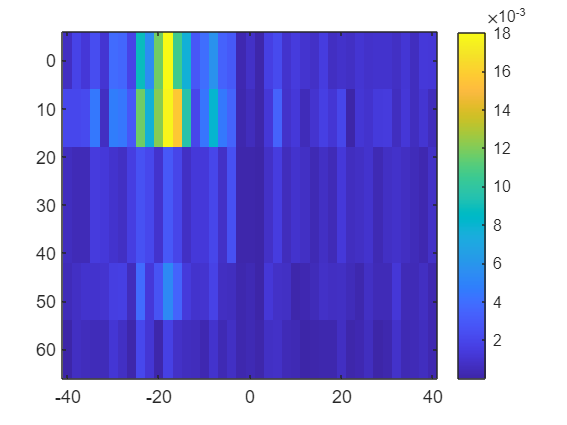


figure;
imagesc(fDs, range_s, abs(cors));
colorbar;

Task 2 Output:

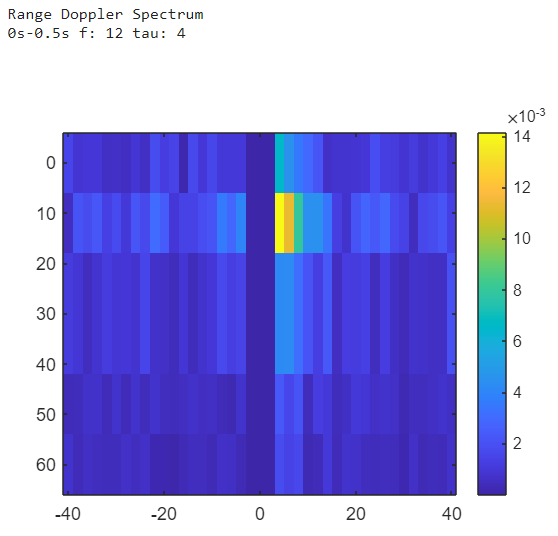

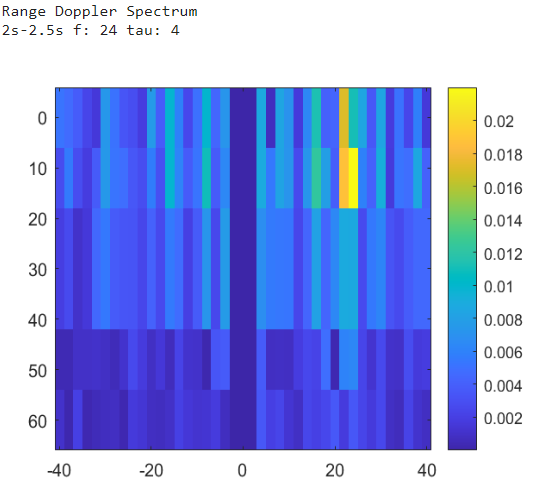

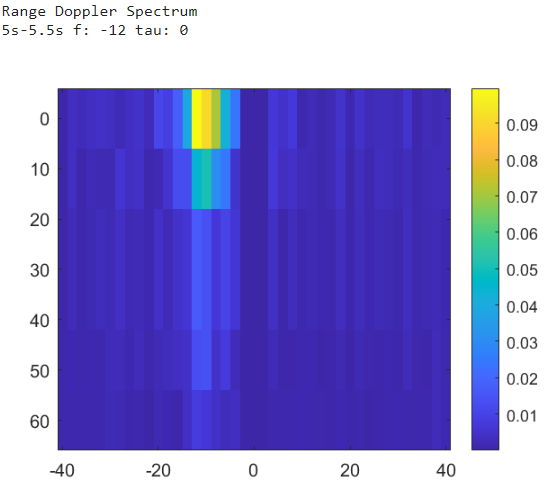

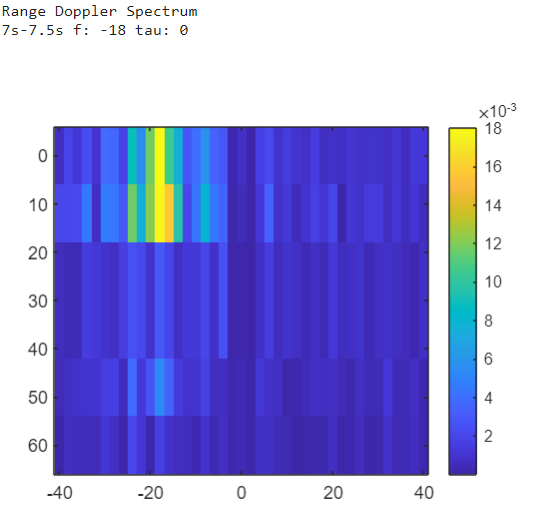

function [tau,fD,cor_max,taus,fDs,cors] = cor(ysur,yref,Ts,tau_min,tau_max,Ntau,fD_min,fD_max,NfD)
yref_conj=conj(yref);
taus=linspace(tau_min,tau_max,Ntau);
Ns=floor(taus/Ts);
fDs=linspace(fD_min,fD_max,NfD);
N=length(ysur);
cors=zeros(Ntau,NfD);
for j=1:Ntau
    for k=1:NfD
        for l=1:N
            if((l-Ns(j))<1)
                yref_conj_current=0;
            else
                yref_conj_current=yref_conj(l-Ns(j));
            end
            cors(j,k)=cors(j,k)+ysur(l)*yref_conj_current*exp(-2i*pi*fDs(k)*(l-1)*Ts);
        end
    end
end
cor_max = max(max(cors));
[tau,fD] = find(cor_max == cors);
end